temp_change = @(T, emissivity, boltz, opt_th, density, C_p) -emissivity .* boltz .* T.^4 ./ (2 .* opt_th .* density .* C_p);
%energy_loss = @(T, emissivity, boltz) 2 * emissivity * boltz * T.^4;

## Initialize material properties

% Values for silicone oil with dye
emissivity = 0.5; 
opt_th = 1;
density = 1; % [g / cm3]
C_p = 1.67; % [J / g]
boltz = 6.570e-8; % [J / K]

## Calculate temperature change over time

T_0 = 300; % [K]
velocity = 10; % [m / s]
distance = 20; % [m]
cross_section = 1; % [m2]
transit_time = distance / velocity; % [s]
[t,T] = ode45(@(t, T) cross_section * temp_change(T, emissivity, boltz, opt_th, density, C_p), [0, transit_time], T_0);

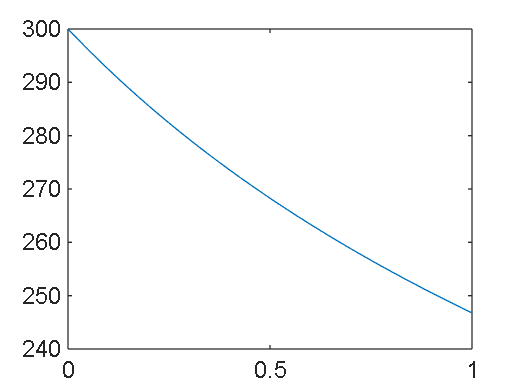

plot(t, T)

T_0 / T(end)

ans =    1.373890807879063


temp_change(T, emissivity, boltz, opt_th, density, C_p)

ans =  -79.666167664670652
 -75.623288434057542
 -71.926320288447442
 -68.534451943081677
 -65.412892781085901
 -62.531915145159651
 -59.865902129400645
 -57.392638587580308
 -55.092794268931790
 -52.949517714272368


T_analytic = (T_0^-3 + cross_section * 3 * emissivity * boltz ./ (2 * opt_th * density * C_p) .* t) .^ (-1/3)

T_analytic = 1.0e+02 *

   2.999999999999999
   2.961192979286019
   2.924319075518197
   2.889215828977185
   2.855739607647628
   2.823762865790411
   2.793171877855845
   2.763864852940404
   2.735750356212983
   2.708745979720265


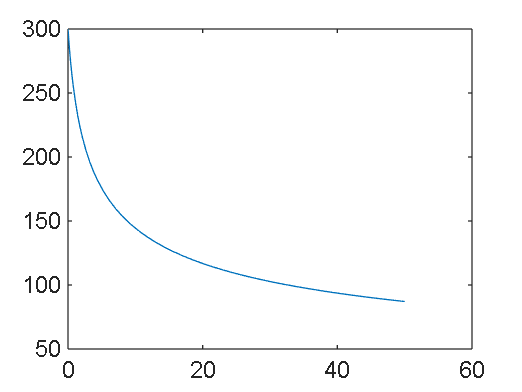

plot(t, T_analytic)

## Calculate heat loss

m_dot = density * cross_section * velocity

m_dot =     10


Q_dot = m_dot * C_p * (T(end) - T_0)

Q_dot =     -1.363421995934188e+03


Q_dot_kW = Q_dot / 1000

Q_dot_kW =   -1.363421995934188


Q_dot_needed = -35000

Q_dot_needed =       -35000


Q_dot / Q_dot_needed

ans =    0.038954914169548


density * cross_section * distance

ans =     20
